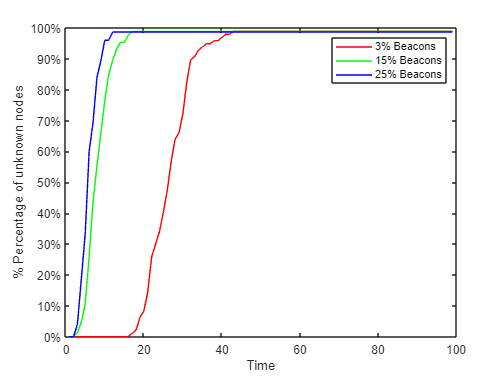

% Array=csvread('nodes_25.csv');
% 
% X = Array(:, 1);
% Y = Array(:, 2);
% beacon = Array(:, 3);
% 
% figure(1);
% for i = 1:size(X)
%     hold on;
%     if beacon(i) == 0
%         plot (X(i),Y(i),'color', [0.5 0.5 0.5],'linestyle','none','marker','.','markersize',20) 
%     else
%         plot(X(i),Y(i), '.r','MarkerSize',30);
%     end
% end

Report_3=csvread('dvhop_report_3.csv');
Report_15=csvread('dvhop_report_15.csv');
Report_25=csvread('dvhop_report_25.csv');

Time = Report_3(:, 1);

ALE_3 = Report_3(:, 3) ./ 97.0;
ALE_15 = Report_15(:, 3) ./ 85.0;
ALE_25 = Report_25(:, 3) ./ 75.0;

figure(2);
plot(Time, ALE_3 * 100,'r', 'DisplayName', '3% Beacons'), hold on
plot(Time, ALE_15 * 100,'g', 'DisplayName', '15% Beacons'), hold on
plot(Time, ALE_25 * 100,'b', 'DisplayName', '25% Beacons'), hold on

legend("show")

xlim([0.0 100.0])
ylim([0.0 100.0])
ytickformat('percentage')
xlabel("Time")
ylabel("% Percentage of unknown nodes")